% Generate an example switching trajectory (eps=0.1 shows reasonably fast
% switching)
rng(5);
%clear variables;
load('systems.mat');
xout = simulate_system(system2, [0 0; 0 0; 0 0], 1e-3, 100000, 0.1);

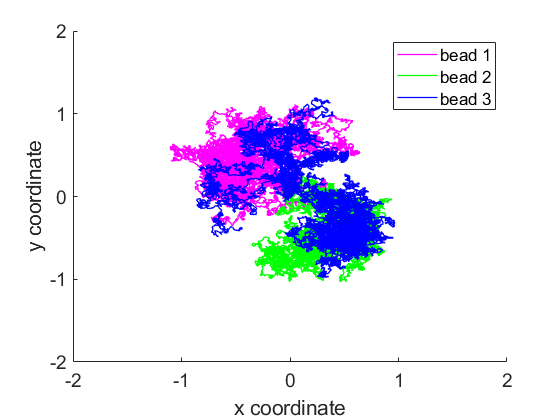

% Create plot of trajectory in 2d space
plot2dbeads(xout(:,:,1:20000));
axis([-2 2 -2 2])
xlabel('x coordinate');
ylabel('y coordinate');
legend('bead 1','bead 2','bead 3')
set(gca, 'FontSize', 14);
saveas(gcf,'figures/2a.png');

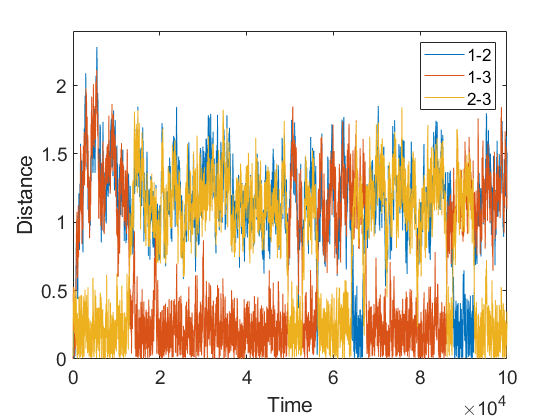

% Create plot of bead-bead distance
plotbeaddist(xout)
set(gca, "FontSize", 14);
saveas(gcf, "figures/2b.png")

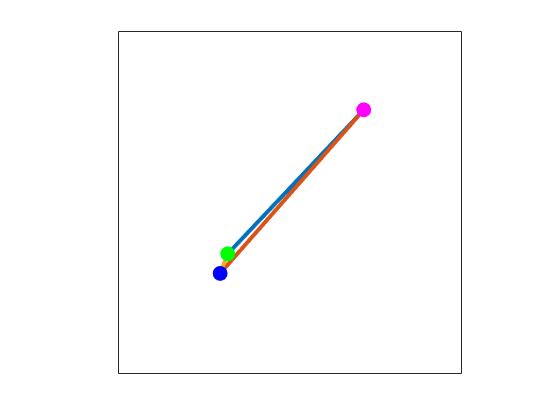

% Plot of beads in bound state
plot2dbeads(xout(:,:,60000));
box on
set(gca,'xtick',[])
set(gca,'ytick',[])
pbaspect([1 1 1])
xlim([-0.90 1.10])
ylim([-1.27 0.73])

saveas(gcf, "figures/2c_bound.png")

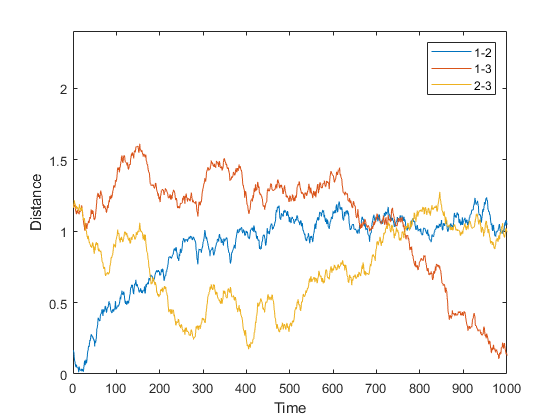

% Plot of beads not in bound state
% First zoom in on transition to identify the right timestep
plotbeaddist(xout(:,:,66700:67700))

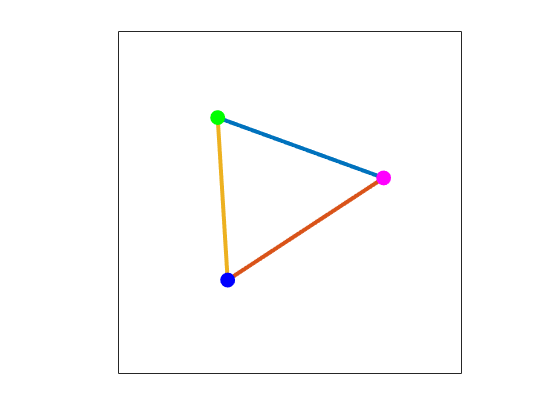

plot2dbeads(xout(:,:,67440))

xlim([-1.05 0.95])
ylim([-0.68 1.32])
box on
set(gca,'xtick',[])
set(gca,'ytick',[])
pbaspect([1 1 1])

saveas(gcf, "figures/2c_tri.png")

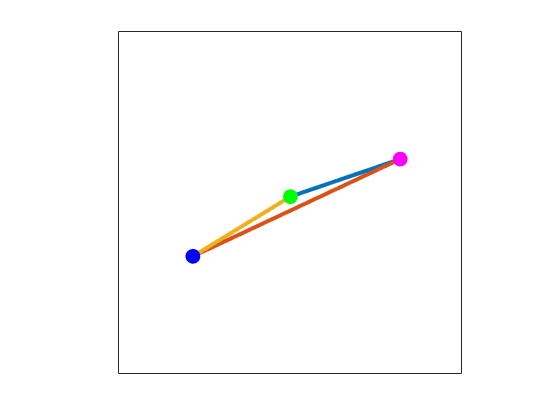

plot2dbeads(xout(:,:,66700+178))
xlim([-1.34 0.66])
ylim([-0.49 1.51])
box on
set(gca,'xtick',[])
set(gca,'ytick',[])
pbaspect([1 1 1])

saveas(gcf,"figures/2c_line.png")

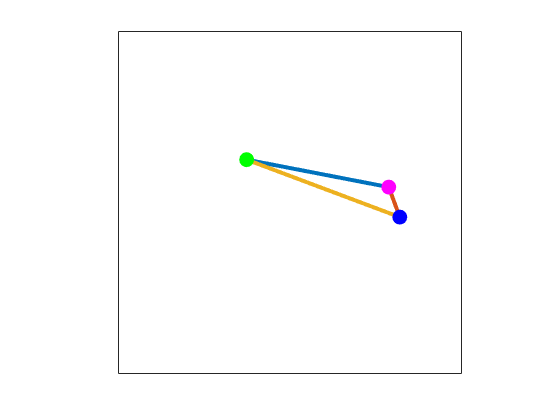

% Plot of beads in bound state
plot2dbeads(xout(:,:,68000));
box on
set(gca,'xtick',[])
set(gca,'ytick',[])
pbaspect([1 1 1])

xlim([-1.818 0.602])
ylim([-1.101 1.319])

saveas(gcf, "figures/2c_bound2.png")